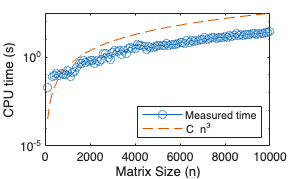

% Andrew Hutsell
% MATH 515
% Problem Set 2

clear; clc; close all;
% Exercise 1
% Create the various matrices that will be used
nvals = 100:100:10000;
% Initialize the array for the times of each matrix solve
t = zeros(size(nvals));

% Iterate through each matrix sixe
for k = 1:length(nvals)
    % Selects the size matrix that will be used
    n = nvals(k);
    % Creates matrix A
    A = magic(n);
    % Used to grab the cpu time at the beginning of the computation
    t0 = cputime;
    % Calcualates the determinant of A
    d = det(A);
    % Stores the total computational time for this solution
    t(k) = cputime-t0;
end

% Calculate the constant C so that the computational time is approximately
% equal to t_n ~ Cn^3
C = mean(t ./ (nvals.^3));

% Creates the plot for the Exercise using semilogy()
semilogy(nvals, t, 'o-')
hold on
semilogy(nvals, C*nvals.^3, '--')
legend('Measured time','C n^3', Location='southeast')
xlabel('Matrix Size (n)')
ylabel('CPU time (s)')

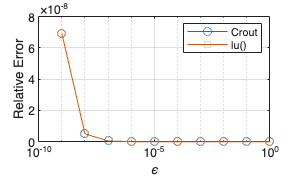

clear; clc; close all;

% Exercise 3

% Part d
% Inputs
eps_vals = 10.^(-(0:9));
rel_err_crout = zeros(size(eps_vals));
rel_err_builtin = zeros(size(eps_vals));

x_exact = [1;1;1];
% iterate through the epsilon values
for k = 1:length(eps_vals)
    % Uses current epsilon value
    eps = eps_vals(k);
    % Matrix A
    A = [2 -2 0;
         eps-2 2 0;
         0 -1 3];
    % Matrix b
    b = [0; 
        eps; 
        2];

    % Crout Method
    n = 3;
    % Initializes Matrices L and U
    L = zeros(n);
    % U is the identity matrix
    U = eye(n);

    for j = 1:n
        for i = j:n
            L(i,j) = A(i,j) - L(i,1:j-1)*U(1:j-1,j);
        end
        for i = j+1:n
            U(j,i) = (A(j,i) - L(j,1:j-1)*U(1:j-1,i))/L(j,j);
        end
    end
    
    y = L\b;
    x_crout = U\y;
    % Calculate the relative error using the crout method
    rel_err_crout(k) = norm(x_crout - x_exact)/norm(x_exact);

    % LU Decomposition in MATLAB
    [L2,U2,P] = lu(A);
    y2 = L2\(P*b);
    x_builtin = U2\y2;
    % Calculate the relative error using lu()
    rel_err_builtin(k) = norm(x_builtin - x_exact)/norm(x_exact);
end

% Plot the results for d
semilogx(eps_vals, rel_err_crout, 'o-', eps_vals, rel_err_builtin, 's-')
xlabel('\epsilon')
ylabel('Relative Error')
legend('Crout','lu()')
grid on

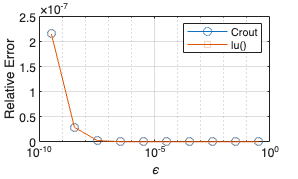



% Part e
% Input values
eps_vals = (1/3)*10.^(-(0:9));
rel_err_crout = zeros(size(eps_vals));
rel_err_builtin = zeros(size(eps_vals));

x_exact = [log(2.5);1;1];
% iterate through the epsilon values
for k = 1:length(eps_vals)
    eps = eps_vals(k);
    % Matrix A
    A = [2 -2 0;
         eps-2 2 0;
         0 -1 3];
    % Matrix b
    b = [2*log(2.5)-2;
         (eps-2)*log(2.5)+2;
         2];

    % Crout Method
    n = 3;
    % Initializes Matrices L and U
    L = zeros(n);
    % U is the identity matrix
    U = eye(n);
    
    % Iterate through each column
    for j = 1:n
        % Computes the column of L
        for i = j:n
            L(i,j) = A(i,j) - L(i,1:j-1)*U(1:j-1,j);
        end
        % Compute Column of U
        for i = j+1:n
            U(j,i) = (A(j,i) - L(j,1:j-1)*U(1:j-1,i))/L(j,j);
        end
    end

    y = L\b;
    x_crout = U\y;
    % Calculate the relative error using the crout method
    rel_err_crout(k) = norm(x_crout - x_exact)/norm(x_exact);

    % LU Decomposition in MATLAB
    [L2,U2,P] = lu(A);
    y2 = L2\(P*b);
    x_builtin = U2\y2;
    % Calculate the relative error using lu()
    rel_err_builtin(k) = norm(x_builtin - x_exact)/norm(x_exact);
end

% Plot the results for e
semilogx(eps_vals, rel_err_crout, 'o-', eps_vals, rel_err_builtin, 's-')
xlabel('\epsilon')
ylabel('Relative Error')
legend('Crout','lu()')
grid on

clear; clc; close all;

% Exercise 4

A = [1 1+0.5e-15 3;
     2 2 20;
     3 6 4];
n = size(A,1);
L = zeros(n);
U = eye(n);

for j = 1:n
    % Compute L(i,j)
    for i = j:n
        L(i,j) = A(i,j);
        for k = 1:j-1
            L(i,j) = L(i,j) - L(i,k)*U(k,j);
        end
    end
    
    % Display after L-column computed
    disp(['After computing column ', num2str(j), ' of L:'])
    L
    U
    % Compute U(j,i)
    for i = j+1:n
        U(j,i) = A(j,i);
        for k = 1:j-1
            U(j,i) = U(j,i) - L(j,k)*U(k,i);
        end
        U(j,i) = U(j,i)/L(j,j);
    end
    % Display after U-row computed
    disp(['After computing row ', num2str(j), ' of U:'])
    L
    U
end

After computing column 1 of L:


L =      1     0     0
     2     0     0
     3     0     0


U =      1     0     0
     0     1     0
     0     0     1


After computing row 1 of U:


L =      1     0     0
     2     0     0
     3     0     0


U =      1.000000000000000e+00     1.000000000000000e+00     3.000000000000000e+00
                         0     1.000000000000000e+00                         0
                         0                         0     1.000000000000000e+00


After computing column 2 of L:


L =      1.000000000000000e+00                         0                         0
     2.000000000000000e+00    -8.881784197001252e-16                         0
     3.000000000000000e+00     2.999999999999999e+00                         0


U =      1.000000000000000e+00     1.000000000000000e+00     3.000000000000000e+00
                         0     1.000000000000000e+00                         0
                         0                         0     1.000000000000000e+00


After computing row 2 of U:


L =      1.000000000000000e+00                         0                         0
     2.000000000000000e+00    -8.881784197001252e-16                         0
     3.000000000000000e+00     2.999999999999999e+00                         0


U =      1.000000000000000e+00     1.000000000000000e+00     3.000000000000000e+00
                         0     1.000000000000000e+00    -1.576259869579674e+16
                         0                         0     1.000000000000000e+00


After computing column 3 of L:


L =      1.000000000000000e+00                         0                         0
     2.000000000000000e+00    -8.881784197001252e-16                         0
     3.000000000000000e+00     2.999999999999999e+00     4.728779608739018e+16


U =      1.000000000000000e+00     1.000000000000000e+00     3.000000000000000e+00
                         0     1.000000000000000e+00    -1.576259869579674e+16
                         0                         0     1.000000000000000e+00


After computing row 3 of U:


L =      1.000000000000000e+00                         0                         0
     2.000000000000000e+00    -8.881784197001252e-16                         0
     3.000000000000000e+00     2.999999999999999e+00     4.728779608739018e+16


U =      1.000000000000000e+00     1.000000000000000e+00     3.000000000000000e+00
                         0     1.000000000000000e+00    -1.576259869579674e+16
                         0                         0     1.000000000000000e+00



disp('Residual R = A - LU')

Residual R = A - LU


R = A - L*U

R =      0     0     0
     0     0     0
     0     0     4


norm_R = norm(R)

norm_R =      4



[Lp,Up,P] = lu(A);
disp('Residual with pivoting RP = P*A - L*U')

Residual with pivoting RP = P*A - L*U


RP = P*A - Lp*Up

RP =                          0                         0                         0
                         0                         0                         0
                         0                         0    -8.881784197001252e-16


norm_RP = norm(RP)

norm_RP =      8.881784197001252e-16
